# ***Inversion_Synthetic_grid.mlx***

Το script αυτό πραγματοποιεί την Αντιστροφή των συνθετικών δεδομένων στην περίπτωση σταθμών GPS διατεταγμένων σε πλέγμα (μικρό σφάλμα). Εαν δεν προηγηθεί το τρέξιμο του script 'Misfit_Roughness_grid.mlx', εισάγονται εκ νέου στο αντίστοιχο σημείο οι παράμετροι της Αντιστροφής.

Αρχικά θέτουμε ως θέση που τρέχει η Matlab το εσωτερικό του φακέλου 'Project'. Όπου υπάρχει σε σχόλιο το "-->", η μεταβλητή πρέπει να εισαχθεί από το χρήστη ανάλογα με τα δεδομένα του προβλήματος.

% Copyright (c) 2018, Livadas – Stathakopoulos Ioannis (yiannislibad@hotmail.gr)
% Covered by MIT Licence
% Πραγματοποιείται εντός αναφορά σχετικά με χρήση scripts ή λογισμικού τρίτων.

% Επιτρέπουμε στη Matlab να έχει πρόσβαση στα περιεχόμενα του φακέλου Project.
folder = fileparts(which('Inversion_Synthetic_grid.mlx'));
addpath(genpath(folder));
clearvars

% Φόρτωση του Workspace που αποθηκεύτηκε από το 'Forward_Modeling_grid.mlx'
load Workspace_ForwardModeling_grid.mat

## Εισαγωγή Παραμέτρων Αντιστροφής

% Εισάγετε New_Par = "1": σε περίπτωση που δεν έχει προηγηθεί εκτέλεση του...
% 'Misfit_Roughness_grid.mlx', ή επιθυμείτε τον εκ νέου καθορισμό των...
% παραμέτρων της Αντιστροφής,...
% ή New_Par = "0": εάν επιθυμείτε τη διατήρηση των ίδιων τιμών παραμέτρων.

New_Par = 0;    % --> Enter "0" or "1"

if New_Par == 0
    if exist('Inv_Par_grid.mat','file')
        load Inv_Par_grid.mat
    else
        disp(['Run ''Misfit_Roughness_grid.mlx'' or' ...
            ' enter "New_Par" value "1"'])
    end

elseif New_Par == 1
    disp('Enter Inversion Parameters')

    % Εισαγωγή παραμέτρων Αντιστροφής, εάν επιλέξαμε εισαγωγή νέων παραμέτρων
    PR = 0.25;                % --> Poisson ratio (default = 0.25, όμοιο με FM)
    PS = 1.0;                 % --> Patch size [km]
    mR = 0; MR = 360;         % --> min-Max Rake [deg] (a-priori)
    MS = 50.0;                % --> Max Slip [m] (a-priori)  
    tD_A = Dip; bD_A = Dip;   % top-bottom Dip of point A (fault trace) [deg]
    tD_B = Dip; bD_B = Dip;   % top-bottom Dip of point B (fault trace) [deg]
    CN = 10000;               % --> Αριθμός κύκλων

    % Εισαγωγή επιθυμητής (βέλτιστης) παραμέτρου k (SF_grid)
    SF_grid = 0.18;                % --> Smoothing factor k

    % Αποθήκευση των παραμέτρων
    save ('Inv_Par_grid.mat','PR','PS','mR','MR','MS','tD_A','bD_A','tD_B','bD_B','CN','SF_grid')

else
    disp('Enter "New_Par" value "0" or "1"')
    
end

## Προετοιμασία της Αντιστροφής για τα συνθετικά δεδομένα

Δημιουργούνται τα αρχεία που θα χρησιμοποιηθούν στο πρόγραμμα 'sdm2011.exe' του R. Wang, για την περίπτωση των συνθετικών μετρήσεων σταθμών σε πλέγμα.

Συντάσσονται τα αρχεία input data για τρεις διευθύνσεις (North, East, Z), τα οποία αποθηκεύονται εντός του υποφακέλου 'GPS_Synthetic_Grid'.

% Μορφολογία σύνταξης των αρχείων input data (για κάθε διεύθυνυση...
    % [lat lon slip error])
dispacement_North = [coordinates_grid_trans 1000*uNgrid_trans ...
    1000*repmat(sigma_uN,points_E*points_N,1)];
displacement_East = [coordinates_grid_trans 1000*uEgrid_trans ...
    1000*repmat(sigma_uE,points_E*points_N,1)];
displacement_Up = [coordinates_grid_trans 1000*uZgrid_trans ...
    1000*repmat(sigma_uZ,points_E*points_N,1)];

mkdir GPS_Synthetic_Grid\


% Δημιουργία αρχείου input data για uN ('coseismic-ns.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_Grid',...
    'coseismic-ns.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', dispacement_North');
fclose(fid);

% Δημιουργία αρχείου input data για uE ('coseismic-ew.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_Grid',...
    'coseismic-ew.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', displacement_East');
fclose(fid);

% Δημιουργία αρχείου input data για uZ ('coseismic-ud.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_Grid',...
    'coseismic-ud.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', displacement_Up');
fclose(fid);

Δημιουργείται και το input αρχείο '**grid.inp**' των synthetic data πλέγματος εντός του υποφακέλου 'sdm2011'.

    % Σύνθεση του input αρχείου 'grid.inp'     
    fid = fopen(fullfile(pwd,'sdm2011','grid.inp'), 'wt');
    fprintf(fid, [' 1\n ' ...
        num2str(PR) '\n' ...
        ' 1\n' ...
        ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
        num2str(PS) '\n ' ...
        num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
        ' 2\n ' ...
        num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
        num2str(bD_A) '\n ' ...
        num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
        num2str(bD_B) '\n ' ...
        ' 3 1.0 0\n' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ns.txt'' ' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ns.txt''\n' ...
        ' 1.00 0 1 90.0 0.0\n' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ew.txt'' ' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ew.txt''\n' ...
        ' 1.00 0 1 90.0 90.0\n' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ud.txt'' ' ...
        ' ''../GPS_Synthetic_Grid/coseismic-ud.txt''\n' ...
        ' 1.00 0 1 0.0 0.0\n' ...
        ' ' num2str(CN) '\n' ...
        ' 1 ' num2str(SF_grid) '\n' ...
        ' ''grid_slip.dat''\n' ...
        ' ''grid_output-un.dat'' ''grid_output-ue.dat''' ...
        ' ''grid_output-uz.dat''']);
    fclose(fid);

## Αντιστροφή συνθετικών μετρήσεων

Βάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' με τις συνθετικές μετρήσεις με μικρό σφάλμα ('grid.inp').

cd sdm2011
commandfile = fopen('commandfile.txt','wt');
fprintf(commandfile,'grid.inp');
fclose(commandfile);
system('sdm2011.exe < commandfile.txt');

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     


delete commandfile.txt
cd ..\.

## Απεικόνιση "προβλέψεων"

Data_Fault_grid = importdata('grid_slip.dat');
Data_Points_grid = importdata('grid_output-ue.dat');

% Εισαγωγή των "προβλέψεων" για τους σταθμούς GPS
inv_uN_grid = Data_Points_grid.data(:,6);
inv_uE_grid = Data_Points_grid.data(:,7);
inv_uZ_grid = Data_Points_grid.data(:,8);

Απεικονίζονται οι "προβλέψεις" μαζί με τα συνθετικά δεδομένα (grid) στο επίπεδο East, North.

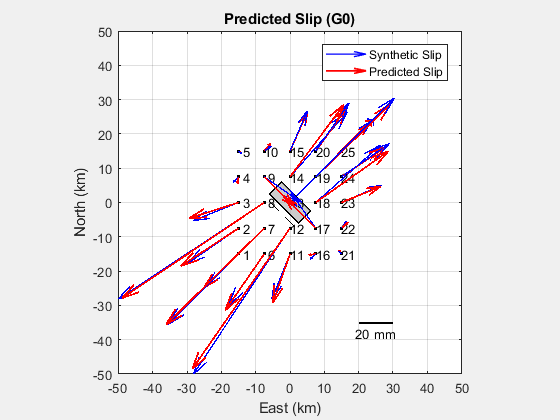

figure()

% Απεικόνιση του ρήγματος
okada85_ed1(Egrid,Ngrid,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
hold on

% Απεικόνιση σημείων - σταθμών GPS
plot3(Egrid,Ngrid,Zgrid,'.k')
text(Egrid_trans,Ngrid_trans,Zgrid_trans,grid_names);

% Απεικόνιση των συνθετικών δεδομένων (grid)
p1 = quiver3(Egrid,Ngrid,Zgrid,uEgrid*Slip_Scale,...
    uNgrid*Slip_Scale,uZgrid*Slip_Scale,'b',...
    'AutoScale','off','MaxHeadSize',0.1,'LineWidth',1);

% Σχεδίαση του ίχνους
plot3(E_trace,N_trace,Z_trace,'k--')

% Απεικόνιση των "προβλέψεων" slip στους σταθμους GPS
p2 = quiver3(Egrid_trans,Ngrid_trans,Zgrid_trans,...
    inv_uE_grid*Slip_Scale/1000,inv_uN_grid*...
    Slip_Scale/1000,inv_uZ_grid*Slip_Scale/1000,...
    'r','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1.3);

% Υπόμνημα
leg = legend([p1 p2],{'Synthetic Slip','Predicted Slip'});
leg.AutoUpdate = 'off';
leg.Location = 'northeast';

% Ticks αξόνων
xticks(-500:10:500)
yticks(-500:10:500)
zticks(-500:10:500)

% Κλίμακα μεγέθους του μέτρου slip
obj = scalebar_ed1;
obj.XLen = 10; obj.YLen = 0;
obj.XUnit = [num2str(1/Slip_Scale*10^6*obj.XLen) ' mm'];
obj.hTextX_Pos = [-1,-3];
obj.Position = [20,-35];

% Labels, εύρος αξόνων, γωνία θέασης και τίτλος
xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
axis([-50 50 -50 50])  % Μεταβάλλω ανάλογα
view([0 90]);          % Για κατακόρυφη προβολή
title('Predicted Slip (G0)')

Και για τις κατακόρυφες ολισθήσεις:

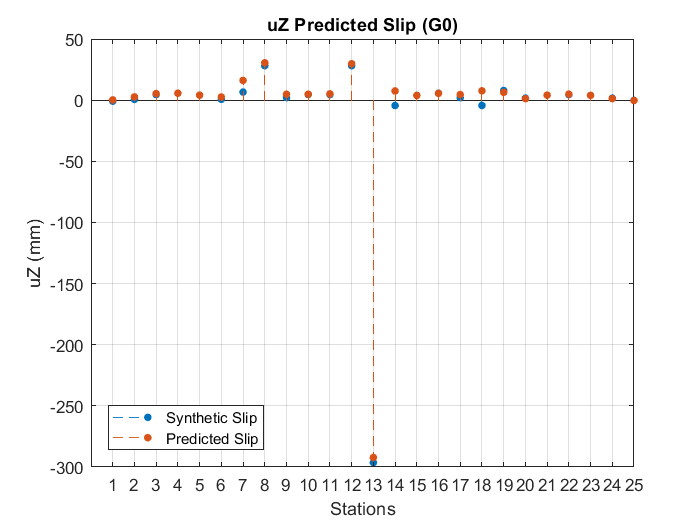

figure()

% Απεικόνιση συνθετικών κατακόρυφων δεδομένων - "προβλέψεων" 
    % κατακόρυφων ολισθήσεων (μορφή stems)
p1 = stem(1:points_E*points_N,[uZgrid_trans*10^6 inv_uZ_grid*1000],...
    'filled','MarkerSize',4,'LineStyle','--');

% Υπόμνημα
leg = legend(p1,{'Synthetic Slip','Predicted Slip'});
leg.AutoUpdate = 'off';
leg.Location = 'southwest';

% Ticks, Labels και τίτλος
grid on
xticks(1:points_E*points_N);
xlabel('Stations'); ylabel('uZ (mm)')
title('uZ Predicted Slip (G0)');

% Αποθήκευση του Workspace
save Workspace_Inversion_Synthetic_grid.mat